# Week 5: significance of regression / correlation

% safety first
close all
clear all
clc

% read in the data
data=xlsread('ATL_MonMeanTemp_1879_2020.xls');
x = data(:,1);
y = data(:,10); % september

% regress
c=cov(x,y);
a=c(1,2)/c(1,1);
b=mean(y)-a*mean(x);

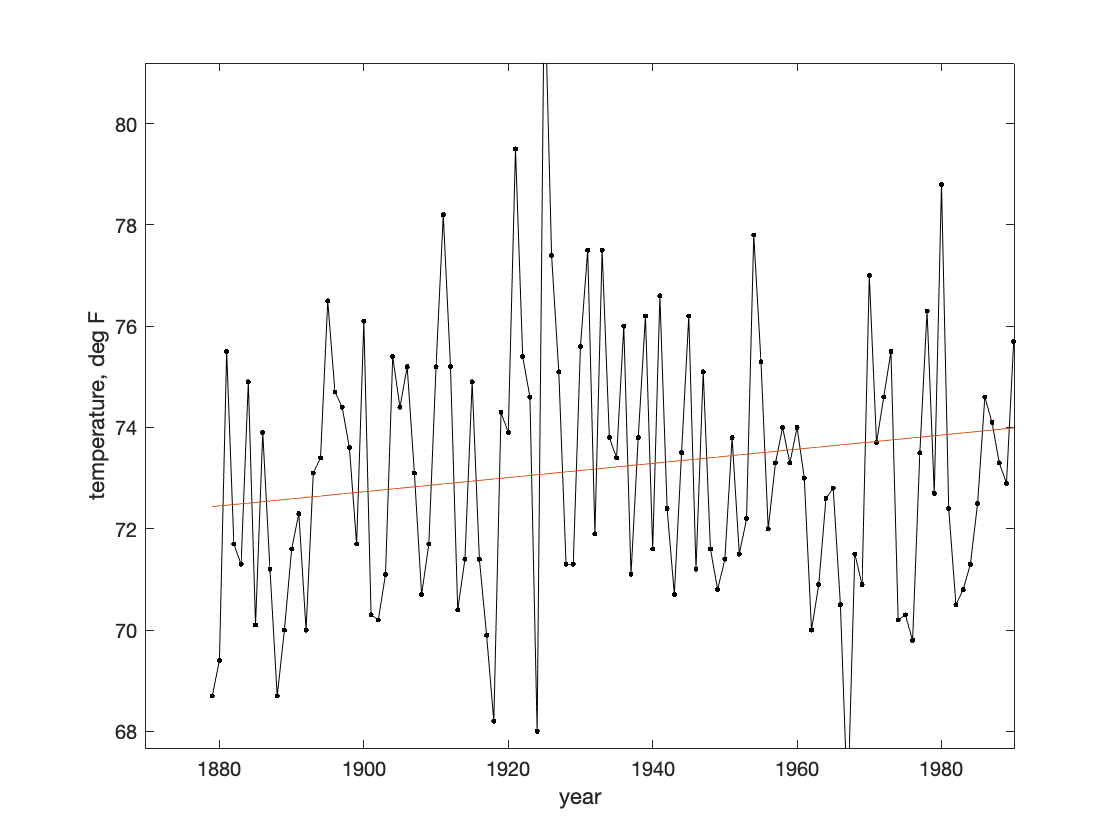

% plot
figure;
plot(x,y,'k.-');
hold on;
plot(x,a*x+b,'-');
hold off;
xlabel('year');
ylabel('temperature, deg F');

% significance test
% 1. confidence level
CL=.99;

% 2. state the hypothesis
% H0: a=0
% H1: a>1

% 3. State the statistics used
% t-test, one-tail

% 4. Calculate critical region
N=length(y);
df=N-2;
alpha=1-CL;
tcrit=tinv(1-alpha,df);
disp(['critical t value is ',num2str(tcrit,3)]);

critical t value is 2.35


% 5. evaluate the hypothesis
MSE = sum((a*x+b-y).^2)/df;
SE2 = MSE/sum((x-mean(x)).^2);
SE = sqrt(SE2);
tval = abs(a)/SE;
disp(['t value is ',num2str(tval,3)]);

t value is 2.53


% calculate the 95% confidence interval on the linear trend
CL = .95;
alpha = 1-CL;
% re-calculate tcrit with two tail
tcrit = tinv(1-alpha/2,df);
disp([num2str(CL*100),' % CI is ', ... 
    num2str(a,3),' (+/-) ',num2str(tcrit*SE,3), ... 

95 % CI is 0.014 (+/-) 0.011 degF/yr


    ' degF/yr']);

### Significance of Correlation

Atlanta vs Seattle

% read in the data
atl=xlsread('ATL_MonMeanTemp_1879_2020.xls');
sea=xlsread('SEA_MonMeanTemp_1894_2020.xls');
sea(sea==-999)=NaN;
atl(atl==-999)=NaN;

% select period after 1901, January
x1=atl(:,1);
y1=atl(:,2);
x2=sea(:,1);
y2=sea(:,2);
% select 1901-2020;
tatl=y1(x1>1900);
tsea=y2(x2>1900);

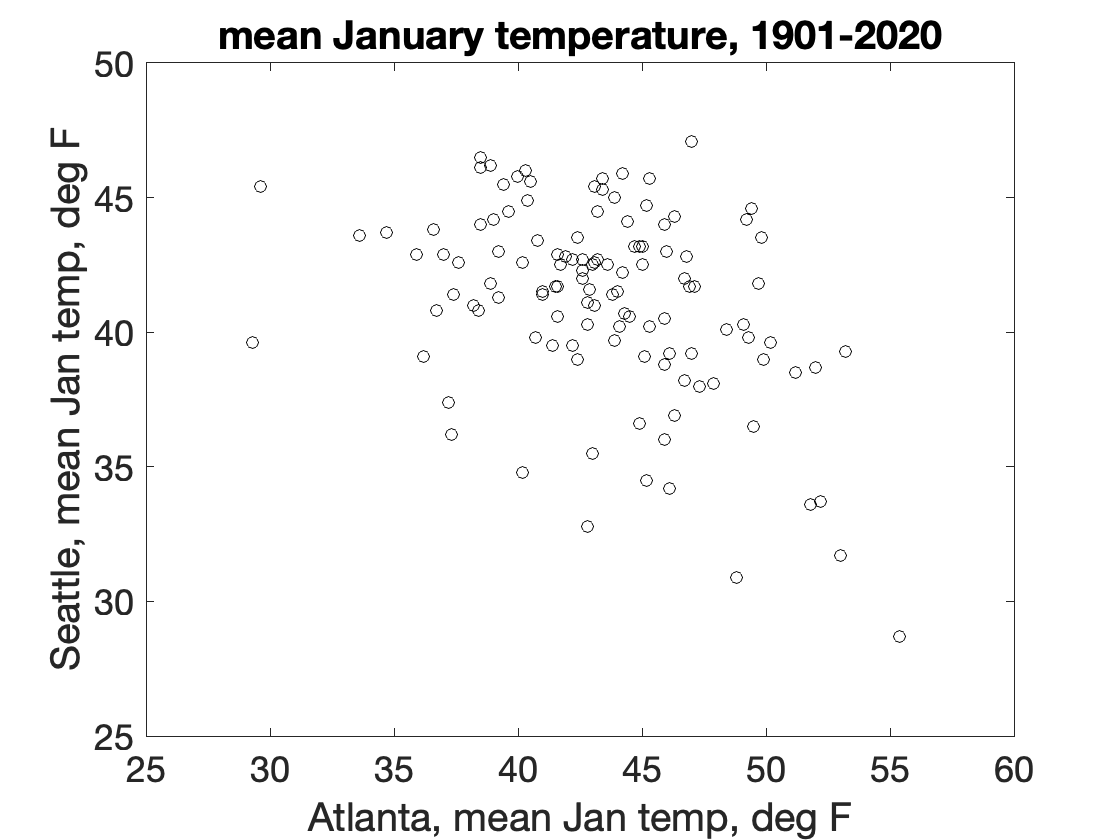

figure;
plot(tatl,tsea,'ko');
xlabel('Atlanta, mean Jan temp, deg F');
ylabel('Seattle, mean Jan temp, deg F');
title('mean January temperature, 1901-2020');
set(gca,'fontsize',18);

% calculate correlation
ind=(~isnan(tatl)) & (~isnan(tsea));
c=cov(tatl(ind),tsea(ind));
r=c(1,2)/sqrt(c(1,1)*c(2,2));
disp(['r = ',num2str(r,3)])

r = -0.407


% critical region
N = length(tatl(ind));
df=N-2;
CL=.99;
alpha=1-CL;
tcrit=tinv(1-alpha,df);
disp(['tcrit = ',num2str(tcrit,3)]);

tcrit = 2.36


% Evaluate
SE = sqrt((1-r^2)/(N-2));
tval = abs(r)/SE;
disp(['[SE,tval] = ',num2str([SE, tval])]);

[SE,tval] = 0.084453      4.8174


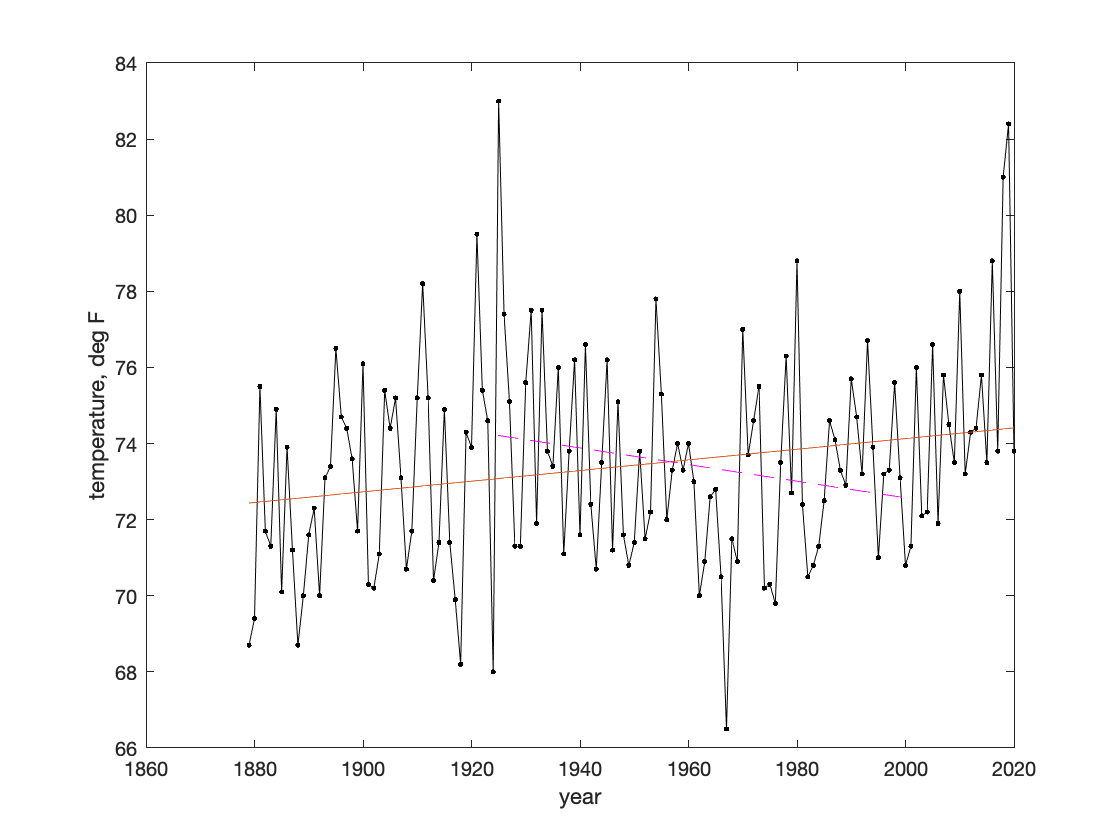

% plot
c1=cov(x(x>=1925&x<=2000),y(x>=1925&x<=2000));
a1=c1(1,2)/c1(1,1);
b1=mean(y(x>=1925&x<=2000))-a1*mean(x(x>=1925&x<=2000));
figure;
plot(x,y,'k.-');
hold on;
plot(x,a*x+b,'-');
plot(x(x>=1925&x<=2000),a1*x(x>=1925&x<=2000)+b1,'m--')
hold off;
xlabel('year');
ylabel('temperature, deg F');